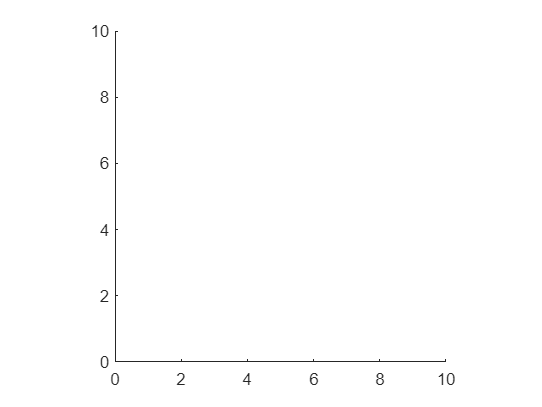

horizon = 2000; % time horizon of the simuation
dt = 0.01; % delta time

% Set up the figure and axis
figure('Position', [100 100 800 600]);
limit = 10;
axis([0 limit 0 limit]);
axis square;
hold on;


% Set up the region
x = linspace(0, limit, 100);
y = linspace(0, limit, 100);

% Initialize the boids
num_boids = 50;
[q, p] = generate_boids(num_boids, limit);
% q = [4.9,2;5.1,8];
% p = [0,1;-0.05,-1];
max_vel = 2;
min_vel = 1.8;
max_accel = 5;
num_collisions = 0;

% System Params
epsilon = 0.1;
r = 0.98*limit;
d = 0.07*limit; 
h = 0.2;
phi_max = 30;
g = 9.8;
% weights for the forces
gradient_coeff = 1.4;
consensus_coeff = 0.0;
turning_coeff = 1e6;

% A lower bound on inter-agent distance, beyond which we consider a collision
d_th = 1e-3;

sys_params = [epsilon, r, d, h, max_accel, phi_max, g, gradient_coeff, consensus_coeff, turning_coeff];

% Update Loop
for i = 1:horizon
    
    neighbours = findNeighbours(q, q, r);
    for j = 1:num_boids
        
        neighbours_of_j = neighbours{j};
        % Find the force acting on the jth boid
        force_on_j = generate_force(q, p, j, neighbours_of_j, sys_params);
        % force_on_j = force_on_j - 1*(q(j,:) - [5,5]);
        % force_on_j = force_on_j;

        %-------------------------- actuator saturation -----------------
        % if vecnorm(force_on_j, 2, 2) > max_accel
        %     force_on_j = (max_accel/vecnorm(force_on_j, 2, 2)) * force_on_j;
        % end

        % ------------------------- velocity control --------------------
        % update velocity
        p(j,:) = force_on_j(1) * p(j,:) / vecnorm(p(j,:),2,2) + p(j,:);
        dtheta = force_on_j(2) * dt;
        p(j,:) = ([cos(dtheta), sin(dtheta); -sin(dtheta), cos(dtheta)] * p(j,:)')';
        if vecnorm(p(j,:), 2, 2) > max_vel
            p(j,:) = (max_vel/vecnorm(p(j,:), 2, 2)) * p(j,:); % cap the velocity at max_vel
        elseif vecnorm(p(j,:),2,2) < min_vel
            p(j,:) = min_vel/vecnorm(p(j,:), 2, 2) * p(j,:);
        end
        p = real(p);
        % update position
        q(j,:) = mod(q(j,:) + p(j,:)*dt, limit); % wraps the boids to within the frame -- exits left, enters right

    end

    % check for collisions
    num_collisions = num_collisions + check_collisions(p, neighbours, d_th);

    a = get_unweighted_adjacency_matrix(q, r);
    g = get_weighted_adjacency_matrix(q, r);
    s = sparse(g);
    scale = limit/25;
    % plots the velocity vectors and positions
    cla;
    % gplot(s,q); 
    quiver([q(:,1)], [q(:,2)], scale*(p(:,1)./vecnorm(p,2,2)), scale*(p(:,2)./vecnorm(p,2,2)), 0, 'Color', 'k'); 
    plot(q(:,1), q(:,2), 'ro', 'MarkerSize', 3.5, 'MarkerFaceColor','red');

    % save the plots at given time intervals
    if mod(i, 1250) == 1
        cla;
        gplot(s,q); 
        quiver([q(:,1)], [q(:,2)], scale*(p(:,1)./vecnorm(p,2,2)), scale*(p(:,2)./vecnorm(p,2,2)), 0, 'Color', 'k'); 
        plot(q(:,1), q(:,2), 'ro', 'MarkerSize', 3.5, 'MarkerFaceColor','red');
        title("t = " + num2str(i/100));
        plot_name = "turning_"+num2str(i/100)+".png";
        exportgraphics(gca, plot_name);
    end 

    % prints the ids of the boids
    % for k = 1:num_boids
    %     text(p(k,1), p(k,2), string(k));
    % end

    % prints the deviation energy, defined in olfati-saber for alpha lattices
    % if mod(i, 1000) == 0
    %     devE = (0.5*sum(psi(g-d))) / (1 + 0.5*sum(a));
    % end

    pause(0.01);
    
end

a_xy =    -2.1363    0.7407


a_xy =    -4.6747   -1.8063


a_xy =    -0.6218    1.2211


a_xy =    -1.1833   -1.3790


a_xy =     0.9007   -2.8244


a_xy =     0.7256   -0.5705



num_collisions
p
vecnorm(p,2,2)

% p1 = p(p(:,2) > 0,:)
% p2 = p(p(:,2) < 0,:)
% delp = p2(1,:) - p1(1,:)
% delp(1)
% l = atan2(delp(1,2)*p1(1,1)-delp(1,1)*p1(1,2), delp(1,1)*p1(1,1)+delp(1,2)*p1(1,2))
% tanh(sin(l/2))
% vecnorm(l,2,2)*tanh(sin(l/2))

function out = generate_force(q, p, id, neighbour_ids, sys_params)

    %-----------------------------------------------------------------
    function out = sigmaEpsilon(z, epsilon)
        out = z ./ sqrt(1 + epsilon*(vecnorm(z, 2, 2)));
    end

    function rho = bumpFunction(z, h)
        rho = zeros(size(z));
        rho(z >= 0 & z < h) = 1;
        rho(z >= h & z <= 1) = (1/2) * (1 + cos(pi * ((z(z >= h & z <= 1) - h)/(1 - h))));
    end

    function out = phi(z, a, b) 
        % merely scaling and shifting the sigmaEpsilon function
        c = abs(a-b)/sqrt(4*a*b);
        out = 0.5 * ((a+b) * sigmaEpsilon(z+c, 1) + (a-b));
    end

    function out  = phi_alpha(z, r_alpha, d_alpha, a, b)
        out = bumpFunction(z/r_alpha, 0.2) .* phi(z-d_alpha, a, b);
    end

    function out = sigmaNorm(z, epsilon)
        out = (1/epsilon) * (sqrt(1 + epsilon * vecnorm(z, 2, 2).^2) - 1);
    end
    %------------------------------------------------------------------

    if isempty(neighbour_ids)
        out = [0,0];
    else

        % q(id,:) -- position of the jth boid
        % q(neighbour_ids,:) -- positions of the neighbouring boids
        % p(id,:) -- velocity of the jth boid
        % p(neighbour_ids,:) -- velocities of the neighbouring boids
    
        % ---------------------- system params ---------------------------
        epsilon = sys_params(1);
        r = sys_params(2);
        d = sys_params(3);
        h = sys_params(4);
        max_accel = sys_params(5);
        phi_max = sys_params(6);
        g = sys_params(7);
        C = g * tand(phi_max);
        kappa = r/d;

        gradient = sys_params(8);
        consensus = sys_params(9);
        turning = sys_params(10);
    
        % --------------------- transformed params -----------------------
        r_alpha = sigmaNorm(r, epsilon);
        d_alpha = sigmaNorm(d, epsilon);

        heading = atan2(p(id, 2), p(id, 1));
        
        % --------------------- gradient term ----------------------------
        n_ij = sigmaEpsilon(q(neighbour_ids,:) - q(id,:), epsilon);
        u_grad = ([cos(heading), sin(heading); -sin(heading), cos(heading)] * sum(phi_alpha(sigmaNorm(q(neighbour_ids,:) - q(id,:), epsilon), r_alpha, d_alpha, 5, 10) .* n_ij, 1)')';
        % u_grad = -sum(phi_alpha(sigmaNorm(q(neighbour_ids,:) - q(id,:), epsilon), r, d, 100000, 100000) .* n_ij, 1);

        % --------------------- consensus term ---------------------------
        a_ij = bumpFunction(sigmaNorm((q(neighbour_ids,:) - q(id,:)/r_alpha), epsilon), h);
        % a_ij = bumpFunction(sigmaNorm((q(neighbour_ids,:) - q(id,:)/r), epsilon), h);
        u_cons = sum(a_ij .* p(neighbour_ids,:) - p(id,:), 1);

        %---------------------- linear acceleration term -----------------
        lin_accel = 0;
        sum_term1 = 0;
        for j = 1:length(neighbour_ids)
            sum_term1 = sum_term1 + sum((p(j,:) - p(id,:)) .* [cos(heading), sin(heading)]);
        end
        lin_accel = tanh(sum_term1) * [cos(heading), sin(heading)];

        %---------------------- turning term -----------------------------
        u_turn = 0;
        sum_term = 0;
        for j = 1:length(neighbour_ids)
            delta_p = p(id,:) - p(j,:);
            eta_ij = atan2(delta_p(2) * p(id,1) - delta_p(1) * p(id,2), sum(delta_p .* p(id,:)));
            if eta_ij == 0 && sum(delta_p .* p(id,:)) < 0
                eta_ij = pi;
            end
            if isnan(eta_ij)
                eta_ij = 0;
            end
            sum_term = sum_term + sin(eta_ij / 2);
        end
        u_turn = -1 / vecnorm(p(id,:),2,2) * tanh(1*sum_term) * [-sin(heading), cos(heading)];
        % --------------------- navigation term --------------------------
        u_nav = [0, 0];
        % u_nav = -100*(q(id,:) - [5,5]);

        %-----------------------------------------------------------------
    
        % u_grad
        % u_cons
        % u_turn
        id;
        % a_xy = gradient*u_grad + consensus*u_cons + u_nav;
        u_grad = gradient*u_grad;
        lin_accel_grad = sum(u_grad .* [cos(heading), sin(heading)]) * [cos(heading), sin(heading)];
        turn_grad = sum(u_grad .* [-sin(heading), cos(heading)]) * [-sin(heading), cos(heading)];
        
        total_lin_accel = lin_accel + lin_accel_grad;
        total_turn = u_turn + turn_grad;

        if abs(total_lin_accel) > max_accel
            total_lin_accel = sign(sum(total_lin_accel.*[cos(heading), sin(heading)])) * max_accel/vecnorm(total_lin_accel,2,2) * [cos(heading), sin(heading)];
        end

        if abs(total_turn) > C/vecnorm(p(id,:),2,2)
            total_turn = (C/vecnorm(p(id,:),2,2)) * (total_turn/vecnorm(total_turn,2,2));
        end

        a_xy = total_lin_accel + total_turn
        % perp

        %-------- convert to x,y to linear,omega acceleration ------------
        % below is the desired control input

        % cap the control inputs and introduce delays 
        % if abs(out(1)) > max_accel
        %     out(1) = out(1)/abs(out(1)) * max_accel;
        % end
        % 
        % if abs(out(2)) > g*tan(phi_max*pi/180) / vecnorm(p(id,:), 2, 2)
        %     out(2) = g*tan(phi_max*pi/180) / vecnorm(p(id,:), 2, 2);
        % end
            
        %-----------------------------------------------------------------
        out = a_xy;
        % set NaN values to zero, else the boid disappears
        out(isnan(out)) = 0;

    end
end


function out = psi(z)
 
    out = z.^2;

end


function neighbors = findNeighbours(boids, all_boids, range)
    
    neighbors = rangesearch(all_boids, boids, range);
    neighbors = cellfun(@(a) a(2:end), neighbors, 'UniformOutput', false);

end


function number_of_collisions = check_collisions(boids, list_of_neighbours, threshold_distance)

    number_of_collisions = 0;
    for i = 1:length(list_of_neighbours)
        neighbours_of_i = list_of_neighbours{i};
        boid_neighbour_distances = vecnorm(boids(i,:) - boids(neighbours_of_i,:), 2, 2);
        number_of_collisions = number_of_collisions + sum(boid_neighbour_distances <= threshold_distance);
    end
    number_of_collisions = number_of_collisions / 2;

end


function out = get_unweighted_adjacency_matrix(points, range)

    function out = cell2logic(c, n)
    out = zeros(1, n);
    out(c) = 1;
    end

    neighbours = findNeighbours(points, points, range);
    out = cell2mat(cellfun(@(a) cell2logic(a, size(points, 1)),  neighbours, 'UniformOutput', false));

end


function out = get_weighted_adjacency_matrix(points, range)

    distances = pdist2(points, points);
    out = get_unweighted_adjacency_matrix(points, range) .* distances;

end
